# Lab 4: OFDM Transmission Using USRP

## [Part 1]

clear;
clc;

## (1) Frame generation

%load("y_win.mat")
N = 64;  
Fs = 10e6;            % Host-side sample rate (computer)
dF = Fs/N;            % Subcarrier spacing
Ncp_STS_smpl = 16;  % Short symbol length (samples)
Ncp_LTS = 32; % LTS cp length
Ncp_data = 16;  % Data CP length
n_rep_STS = 10;
num_data_syms= 5;  % 5 OFDM data symbols (QPSK)

sc_all = (-N/2):(N/2-1);
pilot_sc = [-21 -7 7 21];
data_sc = [-26:-22 -20:-8 -6:-1 1:6 8:20 22:26];  % data tones
active_sc = -26:26;

is_pilot = ismember(sc_all, pilot_sc);
is_data = ismember(sc_all, data_sc);

% STS generation
STS_base = sqrt(13/6)*[...
    0 0 1+1j 0 0 0 -1-1j 0 0 0 1+1j 0 0 0 -1-1j 0 0 0 -1-1j 0 0 0 1+1j ...
    0 0 0 0 0 0 0 -1-1j 0 0 0 -1-1j 0 0 0 1+1j 0 0 0 1+1j 0 0 0 1+1j 0 0 0 1+1j 0 0];

X_STS = zeros(1, N);
active_bins = find(ismember(sc_all, active_sc));
X_STS(active_bins) = STS_base;

sts_symbol = ifft(ifftshift(X_STS), N);
% Repeat 10 times
sts_time = repmat(sts_symbol(1:Ncp_STS_smpl), 1, n_rep_STS);

% LTS generation
LTS_base = [ ...
    1, 1, -1, -1, 1, 1, -1, 1, -1, 1, 1, 1, 1, 1, 1, -1, -1, 1, 1, -1, 1, -1, 1, 1, 1, 1, ...
    0, ...
    1, -1, -1, 1, 1, -1, 1, -1, 1, -1, -1, -1, -1, -1, 1, 1, -1, -1, 1, -1, 1, -1, 1, 1, 1, 1];
X_LTS = zeros(1,N);
X_LTS(active_bins) = LTS_base;
lts_sym = ifft(ifftshift(X_LTS), N);

cp_lts = lts_sym(end-Ncp_LTS+1:end);
lts_time = [cp_lts, lts_sym, lts_sym];


% Data symbols generation
M_data = 4;
DATA_time = complex([],[]);
n_data = numel(data_sc);
n_pil = numel(pilot_sc);
bits_per_sym = n_data * log2(M_data);   % 48*2 = 96 bits per OFDM symbol
total_tx_bits = zeros(num_data_syms * bits_per_sym, 1);
wptr = 1;

mapBPSK = @(b) (1 - 2*b(:));

% pilot_seq = [1 -1 1 -1]; % randomly chosen

for k = 1:num_data_syms
    pilot_bits = randi([0 1], n_pil, 1);
    pilots = mapBPSK(pilot_bits);

    % --- Data bits -> 4QAM
    bits_k = randi([0 1], bits_per_sym, 1);   % unknown data bits
    total_tx_bits(wptr:wptr+bits_per_sym-1) = bits_k;
    wptr = wptr + bits_per_sym;

    data_qpsk = qammod(bits_k, 4, 'gray', 'UnitAveragePower', true, 'InputType','bit');  % 4-QAM

    % --- IFFT bin mapping ---
    Xf = zeros(1, N);
    Xf(is_pilot) = pilots;
    Xf(is_data) = data_qpsk;

    x = ifft(ifftshift(Xf), N);
    xcp = [x(end-Ncp_data+1:end), x];   % 16 + 64 = 80 samples per OFDM symbol
    DATA_time = [DATA_time, xcp]; %#ok<AGROW>
end

pre_zeros  = zeros(1, 100);
post_zeros = zeros(1, 100);

% Full frame with padding
frame = [pre_zeros, sts_time, lts_time, DATA_time, post_zeros];

% Plot
t_us = (0:numel(frame)-1)/Fs * 1e6;

figure; hold on; grid on; box on;
plot(t_us, real(frame), '-',  'LineWidth', 1.1, 'DisplayName','Real');
%plot(t_us, imag(frame), '--', 'LineWidth', 1.1, 'DisplayName','Imag');

% Region indices
idx_pre_end  = numel(pre_zeros);
idx_STS_end  = idx_pre_end + numel(sts_time);
idx_LTS_end  = idx_STS_end + numel(lts_time);
idx_DATA_end = idx_LTS_end + numel(DATA_time);

% Vertical markers
xline(t_us(idx_pre_end),  'r--', 'HandleVisibility','off');
xline(t_us(idx_STS_end),  'r--', 'HandleVisibility','off');
xline(t_us(idx_LTS_end),  'r--', 'HandleVisibility','off');
xline(t_us(idx_DATA_end), 'r--', 'HandleVisibility','off');

% Labels
yl = ylim;
y_top = yl(2);
y_labels = [0.85, 0.70, 0.55, 0.40, 0.25] * y_top;  % stagger vertically

text(t_us(round(idx_pre_end/2)),                 y_labels(1), '100 zeros', 'HorizontalAlignment','center','FontWeight','bold');
text(t_us(round((idx_pre_end+idx_STS_end)/2)),   y_labels(2), 'STS', 'HorizontalAlignment','center','FontWeight','bold');
text(t_us(round((idx_STS_end+idx_LTS_end)/2)),   y_labels(3), 'LTS', 'HorizontalAlignment','center','FontWeight','bold');
text(t_us(round((idx_LTS_end+idx_DATA_end)/2)),  y_labels(4), 'Data: 5 OFDM (QPSK)', 'HorizontalAlignment','center','FontWeight','bold');
text(t_us(round((idx_DATA_end+numel(frame))/2)), y_labels(5), '100 zeros', 'HorizontalAlignment','center','FontWeight','bold');
title('Wi-Fi Frame @ 10 MHz: 100 zeros | STS | LTS | 5×OFDM (QPSK) | 100 zeros');
xlabel('Time (\mus)');
ylabel('Amplitude');
legend('Location','northeast');

## Functions for trainsmission and receive

function [radio_Tx, radio_Rx] = USRP_init_10M(rx_length)
% USRP init for N200/N210/USRP2 with 10 MS/s host rate
    platform  = "N200/N210/USRP2";
    address   = '192.168.10.2';
    fc = 915*1e6;     % center frequency
    txGain_dB = 5;         % tune as needed (avoid clipping)
    rxGain_dB = 5;

    % N210: 100 MHz master; 100e6/10 = 10 MS/s at host
    interp = 10;
    decim  = 10;

    radio_Tx = comm.SDRuTransmitter( ...
        'Platform',          platform, ...
        'IPAddress',         address, ...
        'CenterFrequency',   fc, ...
        'Gain',              txGain_dB, 'InterpolationFactor', interp);
    radio_Rx = comm.SDRuReceiver( ...
        'Platform',          platform, ...
        'IPAddress',         address, ...
        'CenterFrequency',   fc, ...
        'Gain',              rxGain_dB, ...
        'SamplesPerFrame',   rx_length, ...
        'OutputDataType',    'double' , 'DecimationFactor',  decim);
end



function f = find_f(sr,data)
    l = length(data) ; 
    f_axis = linspace(-sr/2,sr/2,l) ; 
    
        
    amp = abs(fftshift(fft(data))) ; 
    [M,I] = max(amp) ; 
    f= abs(f_axis(I)) ; 

end 
% 
% l = 1e3 ; 
% rx_l = l ; 
% [radio_Tx,radio_Rx] = USRP_init_10M(rx_l) ; 
% 
% sr = 1e3 ; 
% t = linspace(0,l/sr,l) ; 
% n = 50 ; 
% f_range = linspace(1,10,n) ; 
% 
% 
% buffer = zeros(n+30,rx_l) ;
% 
% f =1 ; 
% 
% % Transmit and receive for 50 frames 
% for ii =1 : n
%     f = f_range(ii); 
%     data = 1*sin(2*pi*f*t).' ;  
%     tunderrun = radio_Tx(data);
%     [rcvdSignal, ~, toverflow] = step(radio_Rx);
%     buffer(ii,:) = real(rcvdSignal.' ); 
% end 
% 
% % Keep reception for 30 frames 
% for ii = n+1 : n+30
%     [rcvdSignal, ~, toverflow] = step(radio_Rx);
%     buffer(ii,:) = real(rcvdSignal.' ); 
% end 
% 
% 
% 
% release(radio_Tx)
% release(radio_Rx)
% 
% f_buffer = zeros(1,n) ; 
% 
% for ii = 1 : n+30
%     f_buffer(ii) = find_f( sr,buffer(ii,:) ) ; 
% end 
% 
% t = (1:numel(buffer));
% figure; hold on; grid on; box on;
% buffer_reshaped = reshape(buffer, 1, []);
% plot(t(3000:4000), buffer_reshaped(3000:4000));
% figure ;
% plot(f_buffer)
% title(sprintf("Main Frequency component of each frame with frame length = %d",l))
% xlabel("Frame index")
% ylabel("Frequency")


## (2) Transmit and receive the frame

Fs = 10e6; % host-side rate (matches Interp/Decim=10 for 100 MHz) 
Ns_frame = numel(frame); 
% ---- Build one TX packet per iteration: frame + guard zeros (fixed length) ---- 
guard_len = 0; % 80 us of silence @ 10 MS/s (tune 400–2000 as needed) 
tx_one = [frame(:); zeros(guard_len,1)]; % complex column 
Ltx = numel(tx_one); % ---- Backoff to avoid clipping at DAC ---- % 

rx_length = 1.0*Ltx; 
[radio_Tx, radio_Rx] = USRP_init_10M(rx_length); 
l = rx_length; n = 20; 
f_range = linspace(1,10,n);
n = 2000;
buffer = complex(zeros(n+30,rx_length)) ;
THR_POW = 1e-4;
found = false;
det_idx = NaN;
max_scan = n+50;
% Transmit and receive for 50 frames 
for ii = 1 : max_scan 
    tunderrun = radio_Tx(tx_one); 
    [rcvdSignal, ~, toverflow] = step(radio_Rx); % buffer(ii,:) = real(rcvdSignal.' ); 
    buffer(ii,:) = rcvdSignal.' ; 
    received_power = mean(abs(rcvdSignal).^2);
    if ~found && received_power>THR_POW
        found = true;
        det_idx = ii;
        fprintf('Detected strong frame at ii=%d, P=%.3g > THR=%.3g\n', ii, received_power, THR_POW);
        break
    end
end

Detected strong frame at ii=683, P=0.00118 > THR=0.0001




if found
    for jj = 1:30
        [rcvdSignal, ~, toverflow] = step(radio_Rx); %#ok<ASGLU>
        buffer(det_idx+jj,:) = rcvdSignal.';
    end
    last_idx = det_idx + 30;
else
    % If not found, still capture some extra for inspection
    fprintf('No strong frame detected (THR=%.3g). Capturing 30 extra frames anyway.\n', THR_POW);
    for jj = 1:30
        [rcvdSignal, ~, toverflow] = step(radio_Rx); %#ok<ASGLU>
        buffer(max_scan+jj,:) = rcvdSignal.';
    end
    last_idx = max_scan + 30;
end

% Keep reception for 30 frames 
% for ii = n+1 : n+50 
%     [rcvdSignal, ~, toverflow] = step(radio_Rx); % 
%     % buffer(ii,:) = real(rcvdSignal.' ); 
%     buffer(ii,:) = rcvdSignal.' ; 
% end 

release(radio_Tx) 
release(radio_Rx) 
% ---- Quick health checks ---- 
rx_peaks = max(abs(buffer(1:n,:)),[],2); 
fprintf('TX peak after backoff: %.3f | median RX peak: %.3f\n', max(abs(tx_one)), median(rx_peaks));

TX peak after backoff: 0.341 | median RX peak: 0.000


% fprintf('TX peak after backoff: %.3f | median RX peak: %.3f\n', max(abs(tx_one)), median(rx_peaks));

% ---- Pick one received frame and plot with region markers (no correlation yet) ----
buffer_squeezed = reshape(buffer.', 1, []).';
Ncp_LTS = 32;        % LTS CP length (samples)
ST_len = 16;        % short symbol length
sts_len = 10*ST_len; % 10 repeats of 16
LT_len = 64;        % one LTS body
extracted_piece = buffer_squeezed;
x_received = extracted_piece(:).';         % ensure row vector
% x_received = frame;

% ---- LTS matched filter (time-reversed, conjugated) ----
hL = conj(fliplr(lts_sym));           % MF kernel
yL_full = conv(x_received, hL, 'full');
yL = yL_full(1:length(x_received));   % align length

% ---- Two-peak comb: pick two adjacent LTS (LTS1 & LTS2) ----
combL = zeros(1, 2*N);             % length = 128
combL(1) = 1;
combL(N+1) = 1;                          % second peak N samples later

% Convolve comb with |yL| to score aligned double-LTS patterns
zL_full = conv(yL, combL, 'full');
zL= zL_full(numel(combL):end);        % align to x_received

% ---- Peak detection & indices ----
[~, zL_max_index] = max(zL);   
idx_lts1  = zL_max_index;
idx_lts_cp = idx_lts1 - Ncp_LTS;            % CP starts 32 samples before LTS1
idx_sts = idx_lts_cp - sts_len;          % STS region start
idx_data = idx_lts_cp + (Ncp_LTS + 2*N);  % start of data symbols

% Bound to valid range
clip = @(x) max(1, min(x, numel(x_received)));
idx_lts1 = clip(idx_lts1);
idx_lts_cp = clip(idx_lts_cp);
idx_sts = clip(idx_sts);
idx_data = clip(idx_data);

idx_frame_start = idx_sts-100;

idx_sts_one_frame = idx_sts - idx_frame_start + 1;
idx_lts1_one_frame = idx_lts1 - idx_frame_start + 1;
idx_lts_cp_one_frame = idx_lts_cp - idx_frame_start + 1;
idx_data_one_frame = idx_data - idx_frame_start + 1;

x_received_one_frame = x_received(idx_frame_start:idx_frame_start+920-1);

t_us = (0:numel(x_received_one_frame)-1)/Fs * 1e6;

% figure; hold on; grid on; box on;
% plot(t_us, real(y_win), '-',  'LineWidth', 1.0, 'DisplayName','Real');
% plot(t_us, imag(y_win), '--', 'LineWidth', 1.0, 'DisplayName','Imag');

%y_win

figure; hold on; grid on; box on;
plot(t_us, real(x_received_one_frame), '-',  'LineWidth', 1.0, 'DisplayName','Real');
plot(t_us, imag(x_received_one_frame), '--', 'LineWidth', 1.0, 'DisplayName','Imag');
% Known segment lengths at 10 MS/s
xline(t_us(idx_sts_one_frame), 'y-', 'LineWidth',1.2, 'Label','STS start', ...
    'LabelHorizontalAlignment','left','HandleVisibility','off');
xline(t_us(idx_lts_cp_one_frame), 'm-', 'LineWidth',1.2, 'Label','LTS-CP start', ...
    'LabelHorizontalAlignment','left','HandleVisibility','off');
xline(t_us(idx_lts1_one_frame),   'g-', 'LineWidth',1.2, 'Label','LTS1 start', ...
    'LabelHorizontalAlignment','left','HandleVisibility','off');
xline(t_us(idx_data_one_frame),   'r-', 'LineWidth',1.2, 'Label','DATA start', ...
    'LabelHorizontalAlignment','left','HandleVisibility','off');
xline(t_us(idx_data_one_frame+400),   'r-', 'LineWidth',1.2, 'Label','DATA end', ...
    'LabelHorizontalAlignment','left','HandleVisibility','off');


xlabel('Time (\mus)'); ylabel('Amplitude');
title('1st RX frame @ 10 MS/s ');
legend('Location','northeastoutside');

## (3) Matched filter on STS

% Ncp_LTS = 32;        % LTS CP length (samples)
% ST_len = 16;        % short symbol length
% sts_len = 10*ST_len; % 10 repeats of 16
% LT_len = 64;        % one LTS body
% extracted_piece = buffer_squeezed;
% x_received = extracted_piece(:).';         % ensure row vector
% % x_received = frame;
% 
% % ---- LTS matched filter (time-reversed, conjugated) ----
% hL = conj(fliplr(lts_sym));           % MF kernel
% yL_full = conv(x_received, hL, 'full');
% yL = yL_full(1:length(x_received));   % align length
% 
% % ---- Two-peak comb: pick two adjacent LTS (LTS1 & LTS2) ----
% combL = zeros(1, 2*N);             % length = 128
% combL(1) = 1;
% combL(N+1) = 1;                          % second peak N samples later
% 
% % Convolve comb with |yL| to score aligned double-LTS patterns
% zL_full = conv(yL, combL, 'full');
% zL= zL_full(numel(combL):end);        % align to x_received
% 
% % ---- Peak detection & indices ----
% [~, zL_max_index] = max(zL);   
% idx_lts1  = zL_max_index;
% idx_lts_cp = idx_lts1 - Ncp_LTS;            % CP starts 32 samples before LTS1
% idx_sts = idx_lts_cp - sts_len;          % STS region start
% idx_data = idx_lts_cp + (Ncp_LTS + 2*N);  % start of data symbols
% 
% % Bound to valid range
% clip = @(x) max(1, min(x, numel(x_received)));
% idx_lts1 = clip(idx_lts1);
% idx_lts_cp = clip(idx_lts_cp);
% idx_sts = clip(idx_sts);
% idx_data = clip(idx_data);

% ---- Time axis ----
t_us = (0:length(x_received)-1)/Fs * 1e6;

% ---- Plot: LTS MF result & 2-peak score ----
figure; hold on; grid on; box on;
plot(t_us, real(zL),     'LineWidth', 1.2, 'DisplayName','Two-peak score z_L[n]');
plot(t_us, real(yL), '-',        'LineWidth', 1.2, 'DisplayName','|LTS MF|');
plot(t_us, x_received, '--', 'LineWidth', 1.0, 'DisplayName','|x_{rx}|');


% Detected boundaries
xline(t_us(idx_sts), 'y-', 'LineWidth',1.2, 'Label','detected STS start', ...
    'LabelHorizontalAlignment','left','HandleVisibility','off');
xline(t_us(idx_lts_cp), 'm-', 'LineWidth',1.2, 'Label','detected LTS-CP start', ...
    'LabelHorizontalAlignment','left','HandleVisibility','off');
xline(t_us(idx_lts1),   'g-', 'LineWidth',1.2, 'Label','detected LTS1 start', ...
    'LabelHorizontalAlignment','left','HandleVisibility','off');
xline(t_us(idx_data),   'r-', 'LineWidth',1.2, 'Label','detected DATA start', ...
    'LabelHorizontalAlignment','left','HandleVisibility','off');

xlabel('Time (\mus)'); ylabel('Normalized metric');
title('LTS Matched Filter + Two-Peak Comb (detect CP, LTS1, Data start)');
legend('Location','northeast');

% ---- Print indices for debug/report ----
fprintf('Detected STS start: %4d (%.2f us)\n', idx_sts, t_us(idx_sts));

Detected STS start: 653853 (65385.20 us)


fprintf('Detected LTS-CP start: %4d (%.2f us)\n', idx_lts_cp, t_us(idx_lts_cp));

Detected LTS-CP start: 654013 (65401.20 us)


fprintf('Detected LTS1 start  : %4d (%.2f us)\n', idx_lts1, t_us(idx_lts1));

Detected LTS1 start  : 654045 (65404.40 us)


fprintf('Detected DATA start  : %4d (%.2f us)\n', idx_data, t_us(idx_data));

Detected DATA start  : 654173 (65417.20 us)


## (4) Starting index of the first long training symbols

fprintf('Detected LTS1 start  : %4d (%.2f us) in all receiving data.\n', idx_lts1,   t_us(idx_lts1));

Detected LTS1 start  : 654045 (65404.40 us) in all receiving data.


fprintf('Detected LTS1 start  : %4d (%.2f us) in the extracted receiving data.\n', idx_lts1_one_frame,   t_us(idx_lts1)-t_us(idx_frame_start));

Detected LTS1 start  :  293 (29.20 us) in the extracted receiving data.


## (5) Channel estimation for the first LTS

% idx_frame_start = idx_sts-100;
% x_received = x_received(idx_frame_start:idx_frame_start+920-1);
% idx_sts = idx_sts - idx_frame_start + 1;
% idx_lts1 = idx_lts1 - idx_frame_start + 1;
% idx_lts_cp = idx_lts_cp - idx_frame_start + 1;
% idx_data = idx_data - idx_frame_start + 1;

y_lts1 = x_received(idx_lts1 : idx_lts1 + N - 1);
Y1 = fftshift(fft(y_lts1, N));

% Channel estimate using 1st LTS
active_bins = ismember(sc_all, active_sc);
mask_est = active_bins & (sc_all ~= 0);
H1 = nan(1,N);
H1(mask_est) = Y1(mask_est) .* X_LTS(mask_est);

% ----- Plot vs subcarrier index (-26..26) -----
k_plot = sc_all(active_bins);            % -26..26
H_plot = H1(active_bins);  

figure;
subplot(2,1,1); grid on; box on;
plot(k_plot, abs(H_plot), '-o', 'LineWidth', 1.4);
xlabel('Subcarrier index'); ylabel('|H[k]|');
title('Estimated Channel Magnitude (from 1st LTS)');
xlim([min(k_plot) max(k_plot)]);

subplot(2,1,2); grid on; box on;
plot(k_plot, unwrap(angle(H_plot)), '-o', 'LineWidth', 1.4);
xlabel('Subcarrier index'); ylabel('\angle H[k] (rad)');
title('Estimated Channel Phase (from 1st LTS)');
xlim([min(k_plot) max(k_plot)]);

## (6) Channel estimation for the second LTS

y_lts2 = x_received(idx_lts1+N : idx_lts1 + 2*N - 1);
Y2 = fftshift(fft(y_lts2, N));

mask_est = active_bins & (sc_all ~= 0);
H2 = nan(1, N);
H2(mask_est) = Y2(mask_est) .* X_LTS(mask_est);

k_plot = sc_all(active_bins);   % -26..26
H1p = H1(active_bins);       % includes NaN at DC (expected)
H2p = H2(active_bins);

% --- Plot magnitude (same axes) ---
figure;
subplot(2,1,1); grid on; box on;
plot(k_plot, abs(H1p), '-o', 'LineWidth', 1.4, 'DisplayName','|H| from LTS1'); hold on;
plot(k_plot, abs(H2p), '-s', 'LineWidth', 1.4, 'DisplayName','|H| from LTS2');
xlabel('Subcarrier index'); ylabel('|H[k]|');
title('Estimated Channel Magnitude (LTS1 vs LTS2)');
xlim([min(k_plot) max(k_plot)]);
legend('Location','best');

% --- Plot phase (same axes) ---
subplot(2,1,2); grid on; box on;
plot(k_plot, unwrap(angle(H1p)), '-o', 'LineWidth', 1.4, 'DisplayName','∠H from LTS1'); hold on;
plot(k_plot, unwrap(angle(H2p)), '-s', 'LineWidth', 1.4, 'DisplayName','∠H from LTS2');
xlabel('Subcarrier index'); ylabel('\angle H[k] (rad)');
title('Estimated Channel Phase (LTS1 vs LTS2)');
xlim([min(k_plot) max(k_plot)]);
legend('Location','best');

## (7) Subcarrier frequencies

f_DC = 915*1e6;
f_0 = f_DC;
f_m26 = f_DC - 26*dF;
f_p26 = f_DC + 26*dF;
fprintf("Subcarrier spacing = %.2f kHz\n", dF/1000);

Subcarrier spacing = 156.25 kHz


fprintf("Frequency of subcarrier 0 = %.2f MHz\n", f_0/1e6);

Frequency of subcarrier 0 = 915.00 MHz


fprintf("Frequency of subcarrier -26 = %.2f MHz\n", f_m26/1e6);

Frequency of subcarrier -26 = 910.94 MHz


fprintf("Frequency of subcarrier 26 = %.2f MHz\n", f_p26/1e6);

Frequency of subcarrier 26 = 919.06 MHz


## (8) Constellation for the received OFDM 

sym_len = N + Ncp_data;
is_data = ismember(sc_all, data_sc);

% Collect all received data-tone subcarriers from 5 symbols (no EQ)
R_all = [];   % complex constellation points (data tones only)

for k = 0:(num_data_syms-1)
    i0 = idx_data + k*sym_len;                      % CP start of k-th OFDM data sym
    x_with_cp = x_received(i0 + (0:sym_len-1));   
    sym_no_cp = x_with_cp(Ncp_data+1:Ncp_data+N);         % remove CP -> 64
    Yk = fftshift(fft(sym_no_cp, N));               % DC-centered subcarriers
    R_all = [R_all, Yk(is_data)];                   %#ok<AGROW>
end

% Plot constellation (pre-equalization)
figure; hold on; grid on; box on;
plot(real(R_all), imag(R_all), '.', 'MarkerSize', 12);
axis equal; xlabel('In-Phase'); ylabel('Quadrature');
title('Received Constellation (Data Tones, Before Equalization)');

The received symbols are symmetric to the origin (0, 0). It seems that the symbols went under some sort of rotation in phase.

## (9) Channel Equalization using LTS

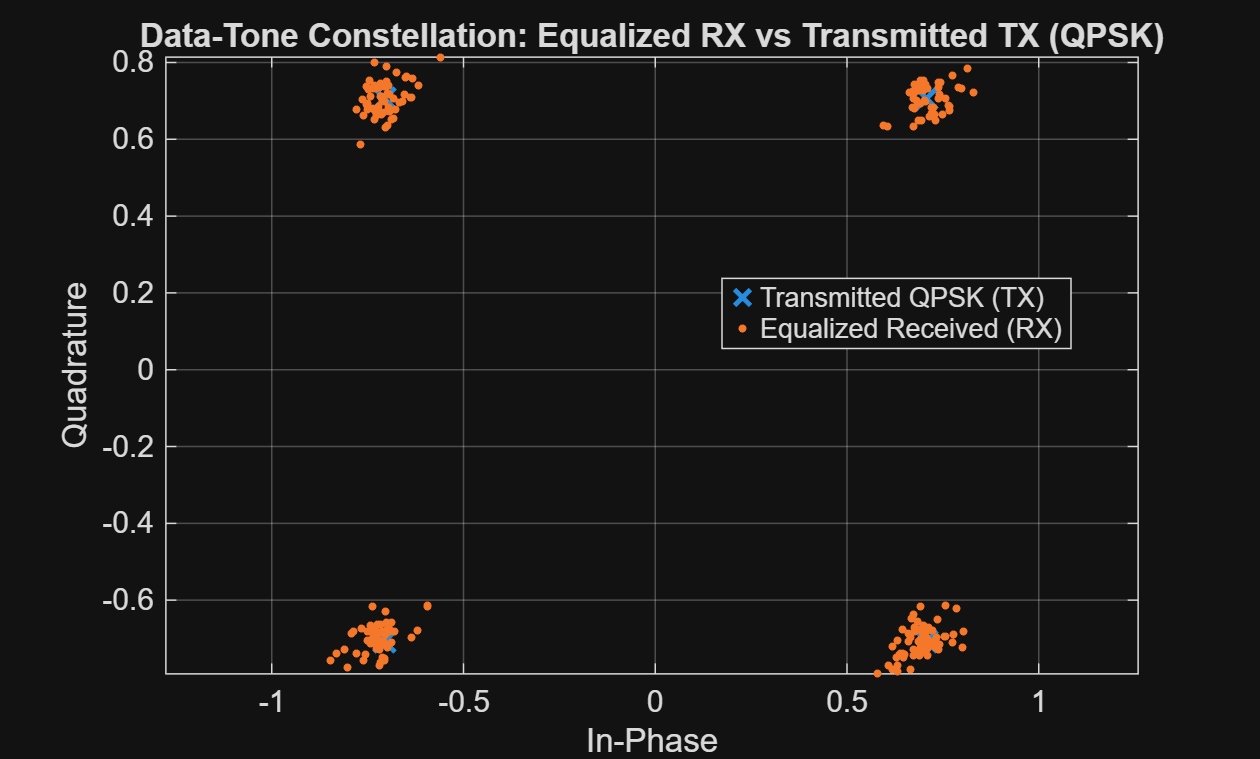

data_tones = find(is_data);

H_est = (H1+H2)/2;
H_data = H_est(is_data);
H_data_safe = H_data; 
H_data_safe(abs(H_data_safe) < 1e-12) = 1e-12;

Y_eq = complex(zeros(num_data_syms*n_data,1)); % equalized RX (data tones only)
wptr = 1;

for k = 0:num_data_syms-1
    % fprintf("k = %d ", k)
    i0 = idx_data + k*sym_len;
    x_cp = x_received(i0 : i0 + sym_len - 1);
    xsym = x_cp(Ncp_data+1:end);                % 64 samples
    Xk = fftshift(fft(xsym, N));  
    X_data = Xk(is_data);                          % data tones only
    Y_equalized = X_data ./ H_data_safe;                    % per-subcarrier EQ
    Y_eq(wptr:wptr+n_data-1) = Y_equalized.';
    wptr = wptr + n_data;
end

% --------- Rebuild transmitted QPSK constellation from total_tx_bits ---------
bits_per_sym = n_data * log2(M_data);           % 48*2 = 96
TX_qpsk = complex(zeros(num_data_syms*n_data,1));
wptr = 1;

for k = 0:num_data_syms-1
    bits_k  = total_tx_bits( (k)*bits_per_sym + (1:bits_per_sym) );  % [96x1]
    sym_idx = bi2de(reshape(bits_k, log2(M_data), []).', 'left-msb');  % [48x1]
    data_qpsk = qammod(bits_k, M_data, 'gray', 'UnitAveragePower', true, 'InputType','bit');
    TX_qpsk(wptr:wptr+n_data-1) = data_qpsk;
    wptr = wptr + n_data;
end

% --------- Plot: Equalized RX vs TX (same axes) ---------
figure; hold on; grid on; box on;
plot(real(TX_qpsk), imag(TX_qpsk), 'x', 'LineWidth', 1.6, 'MarkerSize', 10, ...
     'DisplayName','Transmitted QPSK (TX)');
plot(real(Y_eq),    imag(Y_eq),    '.',  'MarkerSize', 8, ...
     'DisplayName','Equalized Received (RX)');
axis equal; xlabel('In-Phase'); ylabel('Quadrature');
title('Data-Tone Constellation: Equalized RX vs Transmitted TX (QPSK)');
legend('Location','best');

After equalization, the symbols are corrected and gather around the original transmitted symbols

for k = 0:4
    i0   = idx_data + k*(N+Ncp_data);
    x_cp = x_received(i0 : i0 + (N + Ncp_data) - 1).';   % 80 samples
    xs   = x_cp(Ncp_data+1:end);                               % 64 samples (no CP)

    cp_is     = x_cp(1:Ncp_data);         % received CP (16 samples)
    cp_should = xs(end-Ncp_data+1:end);   % last 16 of the 64-sample symbol

    % Robust complex correlation (0..1). Add eps to avoid 0/0.
    num   = abs(sum(conj(cp_should).*cp_is));
    den   = sqrt(sum(abs(cp_should).^2)*sum(abs(cp_is).^2)) + eps;
    cp_match = num/den;
    fprintf('CP match (norm inner product): %.3f\n', cp_match);
end

CP match (norm inner product): 0.997
CP match (norm inner product): 0.997
CP match (norm inner product): 0.999
CP match (norm inner product): 0.992
CP match (norm inner product): 0.994


## (10) SNR or the received

x = x_received(:).';                 % row
L = numel(x);

% ----- Indices for the 5 OFDM data symbols (CP included) -----
sig_start = idx_data;
sig_end = min(L, idx_data + num_data_syms*sym_len - 1);
sig_idx = sig_start:sig_end;

% ----- Indices for padded zeros (pre + post) -----
% pre-zeros: everything before STS start
pre_zero_end = max(1, idx_sts - 1);
pre_idx  = 1:pre_zero_end;

% post-zeros: everything after the 5 data symbols
post_start = min(L, sig_end + 1);
post_idx = post_start:L;

% To be conservative, trim a few samples near boundaries to avoid leakage
trim = 8;  % samples
pre_idx  = pre_idx( 1 : max(0, numel(pre_idx) - trim) );
post_idx = post_idx( min(trim+1, numel(post_idx)) : end );

noise_idx = [pre_idx, post_idx];

% Safety checks
if isempty(sig_idx)
    error('Signal region is empty. Check idx_data and num_data_syms.');
end
if isempty(noise_idx)
    error('Noise region is empty. Ensure padded zeros exist and indices are correct.');
end

% ----- Power calculations -----
P_sig   = mean( abs(x(sig_idx)).^2 );
P_noise = mean( abs(x(noise_idx)).^2 );

SNR_lin = P_sig / max(P_noise, eps);
SNR_dB  = 10*log10(SNR_lin);

fprintf('Samples used -> Signal: %d | Noise: %d\n', numel(sig_idx), numel(noise_idx));

Samples used -> Signal: 400 | Noise: 1866864


fprintf('Signal power: %.4g | Noise power: %.4g | SNR: %.2f dB\n', P_sig, P_noise, SNR_dB);

Signal power: 0.004183 | Noise power: 4.703e-05 | SNR: 19.49 dB
